Sine Wave Array Generator

Author: Michael Noyce

Description: Simple program to generate an array of harmonic sign waves. Array will be in float32_t format to test DSP pipeline on STM32 for the SHARC Buoy 

**Part 1: Accelerometer Simulation**

The  following characteristics are taken from the MPU 6050 datasheet (found here: [MPU6050 Datasheet](https://invensense.tdk.com/wp-content/uploads/2015/02/MPU-6000-Datasheet1.pdf))

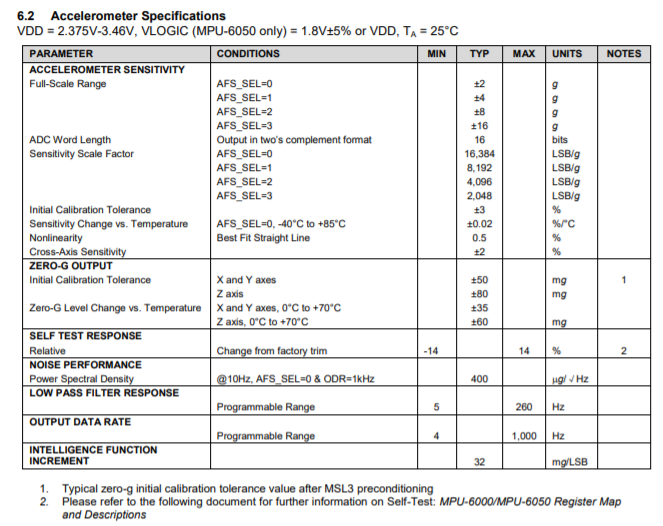

%Start of the Program: Accelerometer Simulation 

%Initially set the accelerometer with ideal parameters
params = accelparams

%Create ideal sinusiod
N = 1024000;
Fs = 500; %Kohout used 640Hz to oversample the initial raw acceleration data
Fc1 = 0.5

t = (0:(1/Fs):((N-1)/Fs)).';
acc = zeros(N, 3);
angvel = zeros(N, 3);
acc(:,1) = 1*sin(2*pi*Fc1*t)

%Create imuSensor object
imu = imuSensor('SampleRate', Fs, 'ReferenceFrame', "NED", 'Accelerometer', params);

%IMU Accelerometer Characteristics
imu.Accelerometer.MeasurementRange = 39.24; % (m/s^2)
imu.Accelerometer.Resolution = 0.0011975; % ((m/s²)/LSB)
imu.Accelerometer.ConstantBias = [0, 0, 0]; % (m/s²)
imu.Accelerometer.AxesMisalignment = [0, 0, 0] % (%)
imu.Accelerometer.NoiseDensity = [0.003924, 0.003924, 0.003924]; %((m/s²)/√Hz)
imu.Accelerometer.BiasInstability = [0.4905, 0.4905, 0.4905]% (m/s²)
imu.Accelerometer.RandomWalk = [0, 0, 0]; %((m/s²)*√Hz)%imu.Accelerometer.TemperatureBias = [0, 0, 0]; %((m/s²)/°C)
%imu.Accelerometer.TemperatureScaleFactor = [0.02, 0.02, 0.02 ] %(%/°C)

%Determine Accelerometer Data output
[accData, ~] = imu(acc, angvel);
%Invert output as NED coordinate system assumes negative accelaration
%values 
accData = -1*accData;

%Plot output compared to ground truth
figure
plot(t, acc(:,1), '--', t, accData(:,1))
xlabel('Time (s)')
ylabel('Acceleration (m/s^2)')
title('Ideal Accelerometer Data')
legend('x (ground truth)', 'x (accelerometer)') 



**Part 2: Gyro Simulation**

The following is takne from the MPU6050 Datasheet:

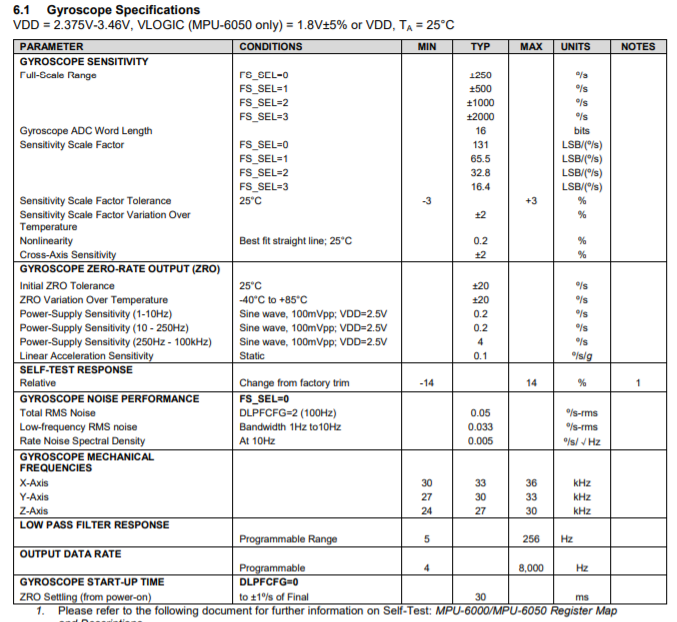

%%Start of Program: Gyroscope Simulaiton  

%Initially set the Gyroscope with ideal parameters
params = gyroparams

%Create ideal sinusiod
N = 1024000;
Fs = 500; %Kohout used 640Hz to oversample the initial raw acceleration data
Fc1 = 0.5

t = (0:(1/Fs):((N-1)/Fs)).';
acc = zeros(N, 3);
angvel = zeros(N, 3);
angvel(:,1) = sin(2*pi*Fc*t);

%Create imuSensor object
imu = imuSensor('SampleRate', Fs, 'Gyroscope', params);


%% Gyroscope Charactersitics
imu.Gyroscope.MeasurementRange = 250.0; % rad/s
imu.Gyroscope.Resolution = 0.00013323; % (rad/s)/LSB
imu.Gyroscope.AxesMisalignment = [0, 0, 0]; % percent
imu.Gyroscope.ConstantBias = [0, 0, 0]; % rad/s
imu.Gyroscope.NoiseDensity = [0.005, 0.005, 0.005]; % (rad/s)/sqrt(Hz)
imu.Gyroscope.BiasInstability = [0, 0, 0]; % rad/s
imu.Gyroscope.RandomWalk = [0, 0, 0]; % (rad/s)*sqrt(Hz)
imu.Gyroscope.TemperatureBias = [0.34907, 0.34907, 0.34907]; % (rad/s)/(degrees C)
%imu.Gyroscope.TemperatureScaleFactor = 3.2; % %/(degrees C)
imu.Gyroscope.AccelerationBias = [0, 0, 0]; % (rad/s)/(m/s^2)

%Seperate
[~, gyroData] = imu(acc, angvel);

figure
plot(t, angvel(:,1), '--', t, gyroData(:,1))
xlabel('Time (s)')
ylabel('Angular Velocity (rad/s)')
title('Ideal Gyroscope Data')
legend('x (ground truth)', 'x (gyroscope)') 


**Part 3: Magnetometer Simulation **

The MPU6050 does not have a magnetometer as it is only a 6 DOF IMU. 